## **第五章**

**5.5 CART算法**

分类与回归树（classification and regression tree, CART）模型由 Breiman 等人在 1984 年提出，是应用广泛的决策树学习方法。CART 同样由特征选择、树的生成及剪枝组成，既可以用于分类也可以用于回归。以下将用于分类与回归的树统称为决策树。 

CART 是在给定输入随机变量 X 条件下输出随机变量 Y 的条件概率分布的学习方法。CART 假设决策树是二叉树，内部结点特征的取值为 “是” 和 “否”，左分支是取值为 “是” 的分支，右分支是取值为 “否” 的分支。这样的决策树等价于递归地二分每个特征，将输入空间即特征空间划分为有限个单元，并在这些单元上确定预测的概率分布，也就是在输入给定的条件下输出的条件概率分布。

CART 算法由以下两步组成：

（1）**决策树生成**：基于训练数据集生成决策树，生成的决策树要尽量大；

（2）**决策树剪枝**：用验证数据集对已生成的树进行剪枝并选择最优子树，这时用损失函数最小作为剪枝的标准。

**已知数据**

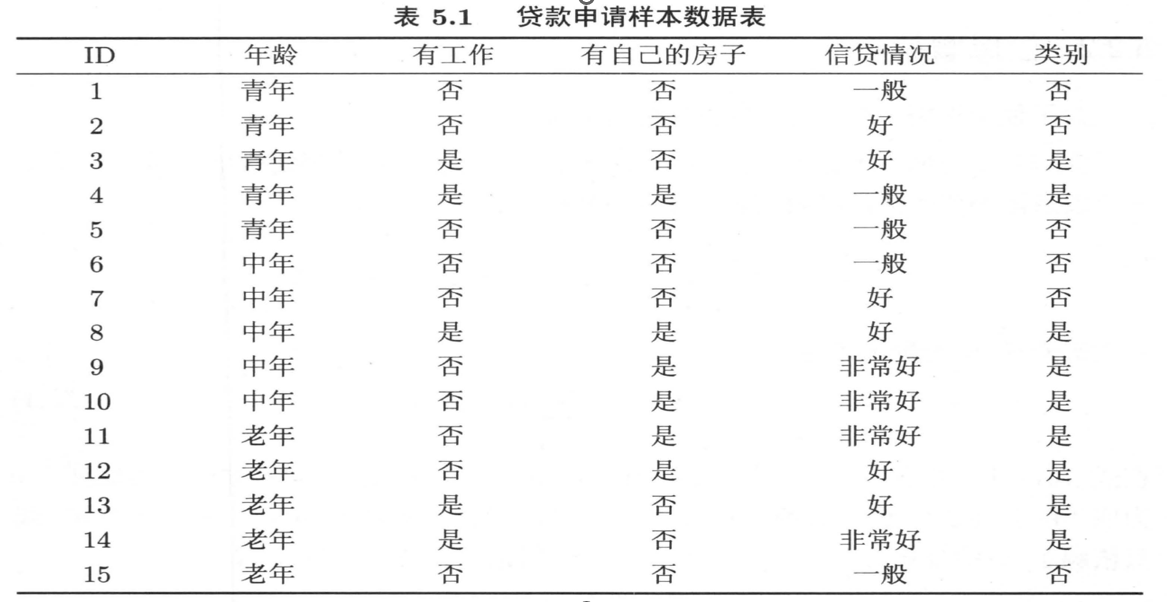

**我们建立分类树的思路是：**对数据8:2进行划分，其中8份为训练集，2份为测试集，采用下图算法，建立出分类树之后，为避免过拟合，利用训练集和测试集对决策树进行检验，判断是否需要进行剪枝，如果需要剪枝我们便使用CART剪枝算法，对决策树进行剪枝，然后再利用训练集和测试集对决策树进行检验，比较前后的预测准确度差异，否则，则不用剪枝

具体构建CART分类树的算法：

 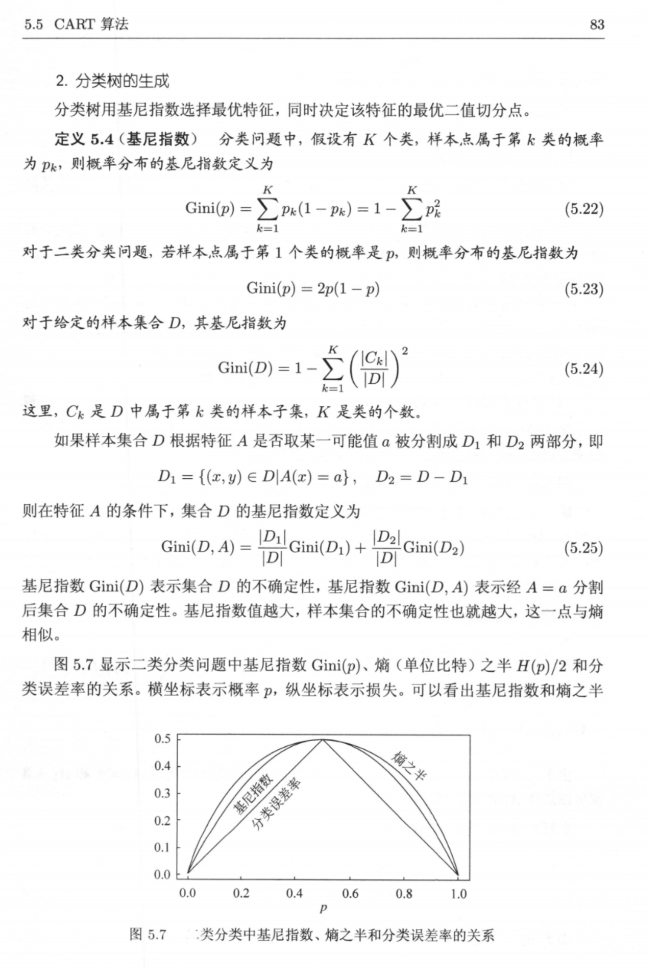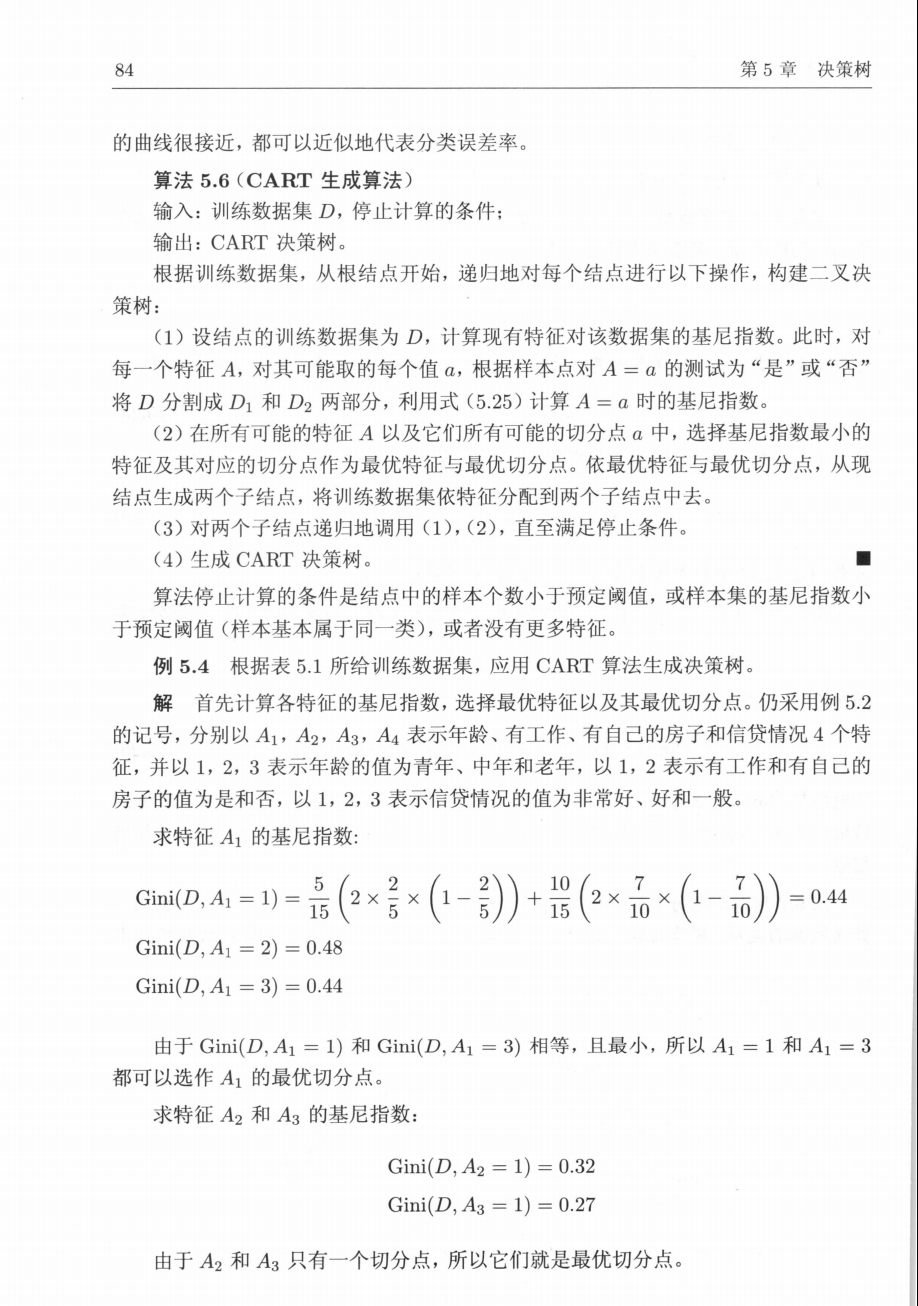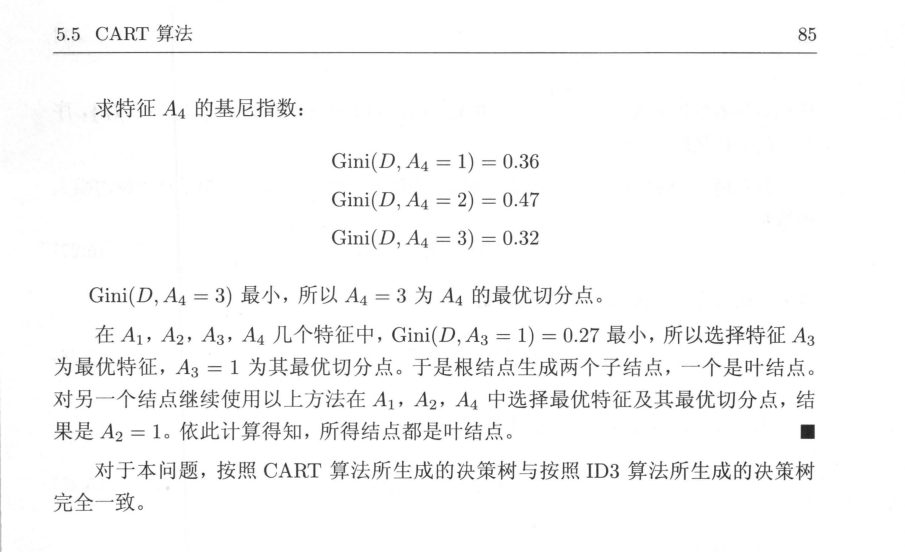

具体剪枝算法：

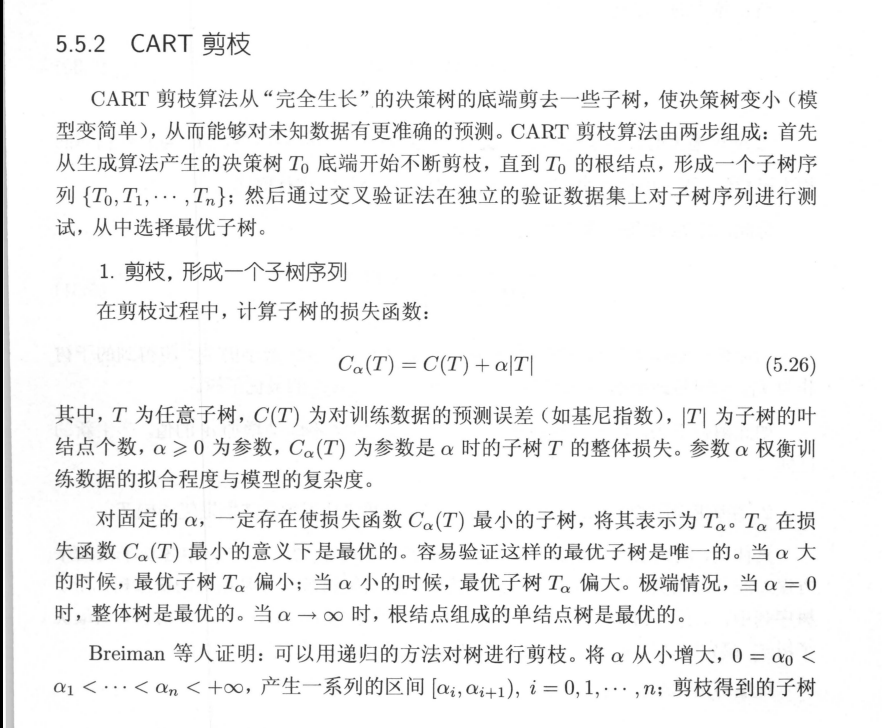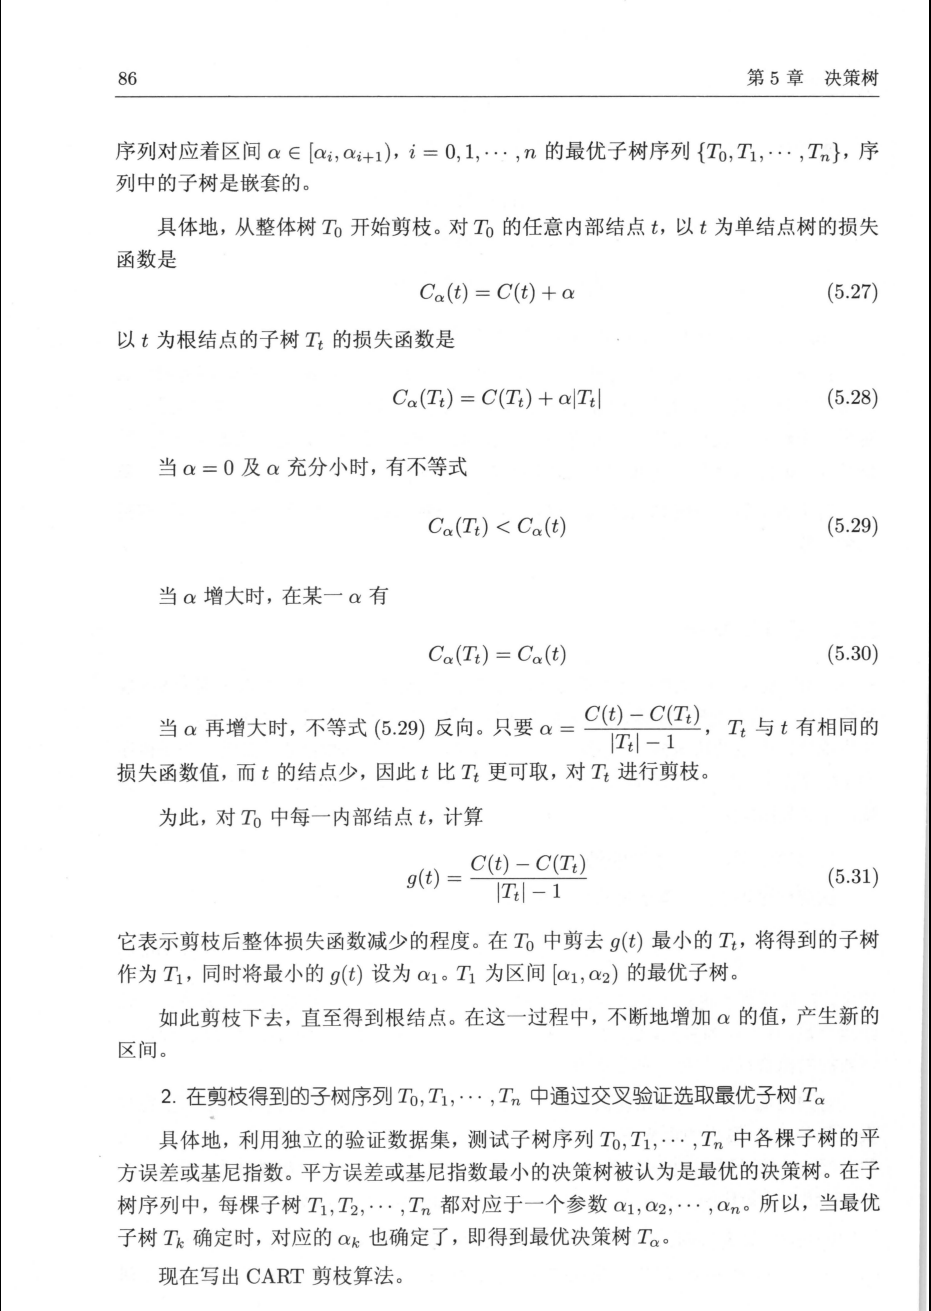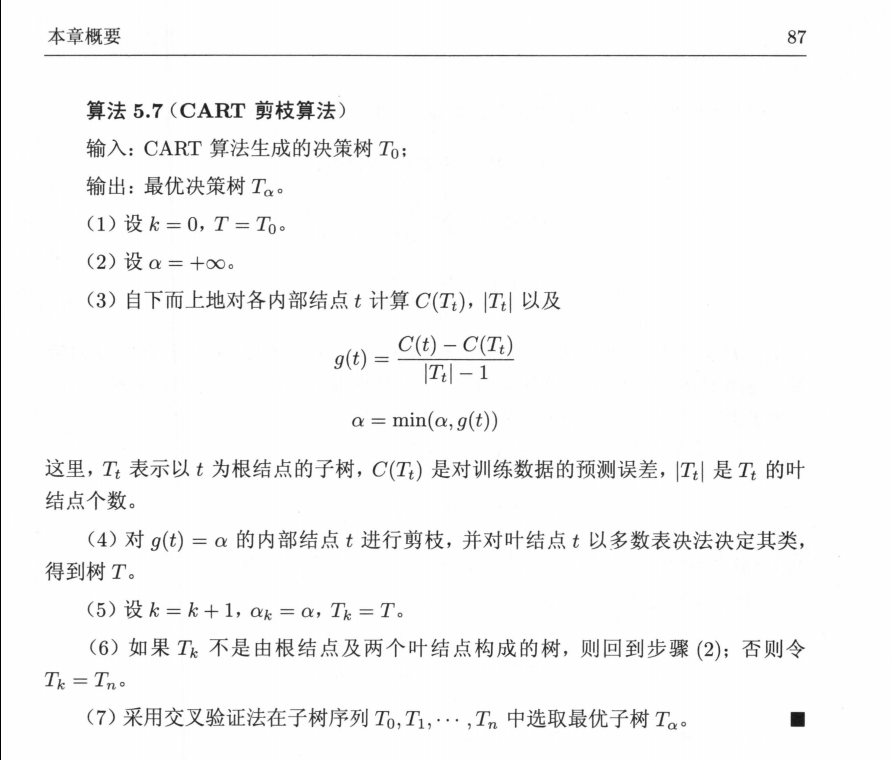

clear; clc; close all;
% 读入数据
rng(0);  % 固定随机种子，保证结果可复现

% 1. 构建贷款数据集（15个样本）  年龄  有工作  有自己的房子  信贷情况  类别
data = [
1 0 0 1 0    % 青年 否 否 一般 否
1 0 0 2 0    
1 1 0 2 1    
1 1 1 1 1    
1 0 0 1 0    
2 0 0 1 0    
2 0 0 2 0    
2 1 1 2 1    
2 0 1 3 1    
2 0 1 3 1    
3 0 1 3 1    
3 0 1 2 1    
3 1 0 2 1    
3 1 0 3 1    
3 0 0 1 0    
];

X = data(:, 1:4);   % 4个特征
y = data(:, 5);     % 标签（0/1）
n = size(X, 1);

% 2.8:2 划分训练集 / 测试集
% 随机打乱整数序列，生成随机不重复序列
% 随机获取80%的训练集，20%的测试集
idx = randperm(n);
% 计算训练数目
train_num = round(0.8*n);
% 获取训练集以及测试集
X_train = X(idx(1:train_num),:);
y_train = y(idx(1:train_num),:);
X_test = X(idx(train_num+1:end),:);
y_test = y(idx(train_num+1:end),:);

fprintf('训练集数量：%d\n', length(X_train));

训练集数量：12


fprintf('测试集数量：%d\n', length(y_test));

测试集数量：3


fprintf('===================================\n');

%% ===================== 子函数=====================
% 1. 计算基尼指数
function gini = calcGini(label)
    if isempty(label)
        gini = 0;
        return;
    end
    p0 = sum(label == 0) / length(label);  % 频数表示概率
    p1 = sum(label == 1) / length(label);
    gini = 1 - p0^2 - p1^2;
end

% 2. 根据特征和阈值划分数据集
function [leftX, leftY, rightX, rightY] = splitData(X, Y, feat, val)
    leftIdx = X(:, feat) <= val;
    rightIdx = ~leftIdx;
    
    leftX = X(leftIdx, :);
    leftY = Y(leftIdx);
    rightX = X(rightIdx, :);
    rightY = Y(rightIdx);
end

% 3. 递归构建CART决策树
function node = buildTree(X, Y)
    % 初始化节点为叶节点
    node.isLeaf = 1;
    node.label = mode(Y);  % 叶节点标签，求众数
    node.feat = 0;
    node.val = 0;
    node.left = [];
    node.right = [];
    
    % 如果所有标签相同，直接返回叶节点
    if length(unique(Y)) == 1
        return;
    end
    % 初始化最优值
    [m, d] = size(X);
    bestGini = 1;
    bestFeat = 1;
    bestVal = X(1, 1);
    
    % 遍历所有特征和所有取值，找最优分裂
    for f = 1:d
        vals = unique(X(:, f));
        for v = vals'
            [~, y1, ~, y2] = splitData(X, Y, f, v);
            currentGini = (length(y1)/m)*calcGini(y1) + (length(y2)/m)*calcGini(y2);
            
            if currentGini < bestGini
                bestGini = currentGini;
                bestFeat = f;
                bestVal = v;
            end
        end
    end
    
    % 执行分裂
    [x1, y1, x2, y2] = splitData(X, Y, bestFeat, bestVal);
    node.isLeaf = 0;
    node.feat = bestFeat;
    node.val = bestVal;
    node.left = buildTree(x1, y1);
    node.right = buildTree(x2, y2);
end

% 4. 单样本预测
function res = predOne(node, x)
    if node.isLeaf          % 如果是叶子节点
        res = node.label;   % 直接输出标签（0或1）
        return;
    end
    
    % 如果不是叶子，就判断走左还是走右
    if x(node.feat) <= node.val
        res = predOne(node.left, x);   % 走左子树
    else
        res = predOne(node.right, x);  % 走右子树
    end
end


% 5. 批量样本预测
function pred = predictTree(tree, X)
    n = size(X, 1);
    pred = zeros(n, 1);
    for i = 1:n
        pred(i) = predOne(tree, X(i, :));
    end
end

%% ===================== 主程序=====================
% 构建CART树
tree_unpruned = buildTree(X_train, y_train);

% 测试精度
train_pred = predictTree(tree_unpruned, X_train);
test_pred = predictTree(tree_unpruned, X_test);

acc_train_unpruned = sum(train_pred == y_train) / length(y_train);
acc_test_unpruned = sum(test_pred == y_test) / length(y_test);

fprintf('===== 决策树 =====\n');

===== 决策树 =====


fprintf('训练集准确率：%.2f%%\n', acc_train_unpruned * 100);

训练集准确率：100.00%


fprintf('测试集准确率：%.2f%%\n', acc_test_unpruned * 100);

测试集准确率：100.00%


fprintf('===================================\n'); % 训练集准确率和测试集准确率相同且均为100%，模型拟合度较好且未过拟合

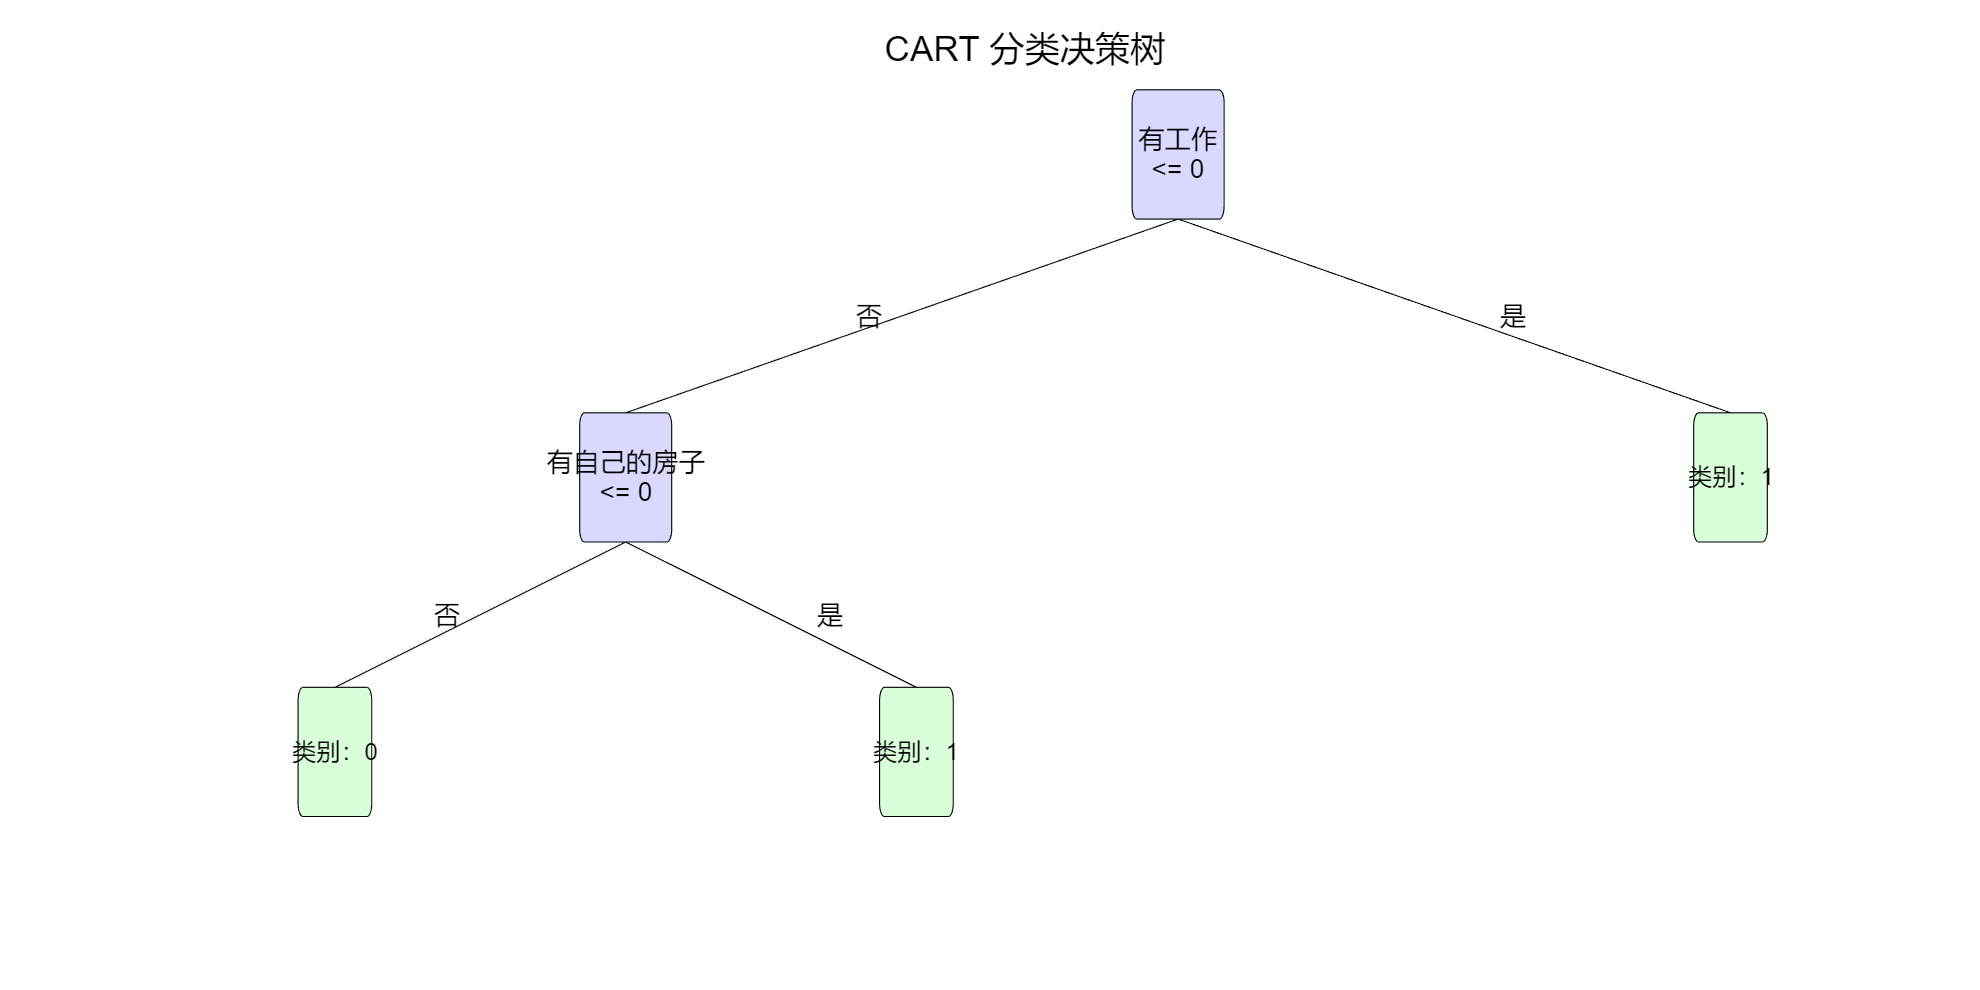

% 函数：画出决策树
function plot_my_tree(tree, feature_names)
    figure('Color','white','Position',[100,100,1200,600]);
    hold on;
    axis off;
    title('CART 分类决策树','FontSize',16);
    
    % 递归画整棵树
    draw_tree(tree, 0, 0, 18, 4, feature_names);
end

function draw_tree(node, x, y, h_step, v_step, feature_names)
    % 叶子节点：只显示类别
    if node.isLeaf
        rectangle('Position',[x-1.2,y-0.8,2.4,1.6],...
            'Curvature',0.2,'FaceColor',[0.85 1 0.85]);
        text(x, y, sprintf('类别：%d', node.label),...
             'HorizontalAlignment','center','FontSize',11);
        return;
    end
    
    % 内部节点
    feat_name = feature_names{node.feat};
    node_str = sprintf('%s\n<= %.0f', feat_name, node.val);
    
    rectangle('Position',[x-1.5,y-0.8,3,1.6],...
        'Curvature',0.2,'FaceColor',[0.85 0.85 1]);
    text(x, y, node_str,...
         'HorizontalAlignment','center','FontSize',12);
    
    % 左分支标注：否 / 不满足
    line([x, x-h_step], [y-0.8, y-v_step+0.8], 'Color','black');
    text((x+x-h_step)/2-1.5, (y + y-v_step)/2, '否','FontSize',12);
    draw_tree(node.left, x-h_step, y-v_step, h_step/1.9, v_step*0.85, feature_names);
    
    % 右分支标注：是 / 满足
    line([x, x+h_step], [y-0.8, y-v_step+0.8], 'Color','black');
    text((x+x+h_step)/2+1.5, (y + y-v_step)/2, '是','FontSize',12);
    draw_tree(node.right, x+h_step, y-v_step, h_step/1.9, v_step*0.85, feature_names);
end

% 调用
feature_names = {'年龄','有工作','有自己的房子','信贷情况'};
plot_my_tree(tree_unpruned, feature_names);